# In the Name of GOD

## Part1: Reading file and understanding the sampling frequency

[y,Fs] = audioread('mefsin.wav');
L=length(y);

Sampling frequency is equal to 16000 hz.

## Part2: Plotting audio signal 

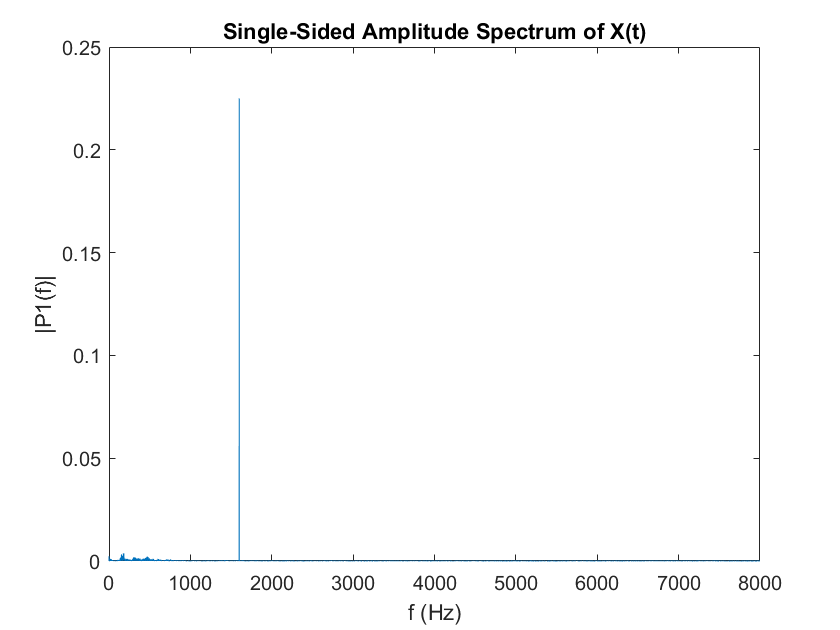

f = Fs*(0:((L/2)-1))/L;
Y = fft(y);
P2 = abs(Y/L);
P1 = P2(1:L/2);
plot(f,P1);
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

## Part3: h[n] of the filter

format
syms z;
hz=(1-1.618*(z^-1)+(z^-2));
hn=iztrans(h)

Undefined function or variable 'h'.

As you can see the frequency of our tone is equal to 1600 hz which is equal to: 0.2*(Fs/2) .

Also values of h[n] are:{1,-1.618,1} .

## Part4: Plotting and playing filtered audio file

[filtered_data,Fs] = audioread('filtered_audio.wav');
sound(filtered_data, Fs);
figure(2)
mefsin_filtered_spec = abs(fftshift(fft(filtered_data)/length(Audio_File)));
f = (-Fs/2:Fs/(L-1):Fs/2);
plot(f, mefsin_filtered_spec)
title('Double-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')